%% unpack from saved file
pcname = char(java.net.InetAddress.getLocalHost.getHostName);
if strcmp(pcname, 'Lenovo-PC')
    imgDir = 'C:\DFiles\Geophysics\Project\Figs_Crosswell';
    rayDir = 'C:\DFiles\Geophysics\Inversion\Shuster_labs\Raytracinglab';
elseif strcmp(pcname, 'Wenyuan-PC')
    imgDir = 'E:/Geophysics/Project/Crosswell/FWI_2arr';
    rayDir = 'E:\Geophysics\Inversion\Shuster_labs\Raytracinglab';
else
    error('PC name not recognized');
end


addpath(rayDir);
% path to save figure
figDir = fullfile(pwd, 'Figures');

fmod1 = 'vp22_pad_smooth.mat';
mod1 = load(fullfile(imgDir, fmod1));
if mod1.fastz
    vel = mod1.vpGaussBlur';
    vel0 = mod1.vp';
else 
    vel = mod1.vpGaussBlur;
    vel0 = mod1.vp;
end
sln = 1./vel;
refl_ss=(sln-1./vel0)./sln;
[nz, nx] = size(vel); dx = mod1.dx; dz = mod1.dz;
x = (0:nx-1)*dx; z = (0:nz-1)*dz;
% source and receiver geometry
idsrc=53;  
sx = mod1.xsrc(idsrc); sz = mod1.zsrc(idsrc); gx = mod1.xrec; gz = mod1.zrec; 
g=1:numel(gx);
%% FD params
nbc=40; nt=double(mod1.nt); dt=mod1.dt; t=(0:nt-1)*dt; isFS=false; 
s=ricker(mod1.fc,dt);
% get common shot gather
csg0 =CSG(sx, sz, gx, gz);
csg0 = csg0.getSeis(vel,nbc,dx,nt,dt,mod1.fc,isFS);

Computing shot gather at sx=0.00m sz=52.00m ... 
Elapsed time is 7.112670 seconds.


% get first arrival time
csg0 = csg0.getFirstArrival();

Computing time table sx=0.00m sz=52.00m... 
Elapsed time is 37.325975 seconds.


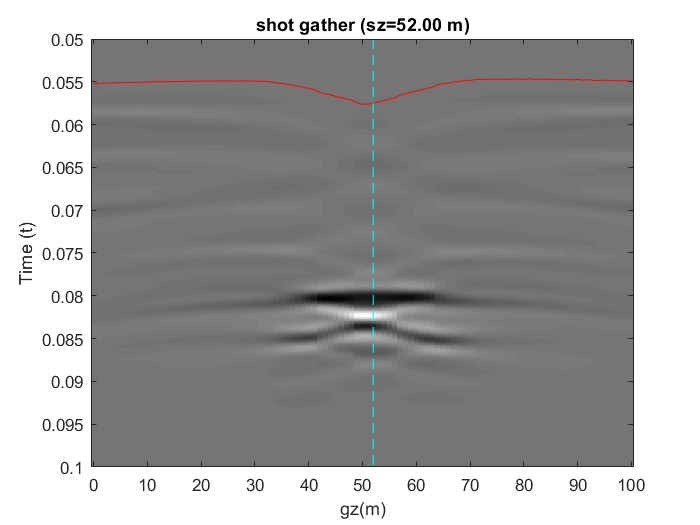

% choose trace 
idxTrace = idsrc; 
hdCSG = csg0.plotCSG('FA', 'y', 'ylim', [0.05, 0.1], 'idxTrace', idxTrace);
csg0.saveseis(hdCSG, 'gather');

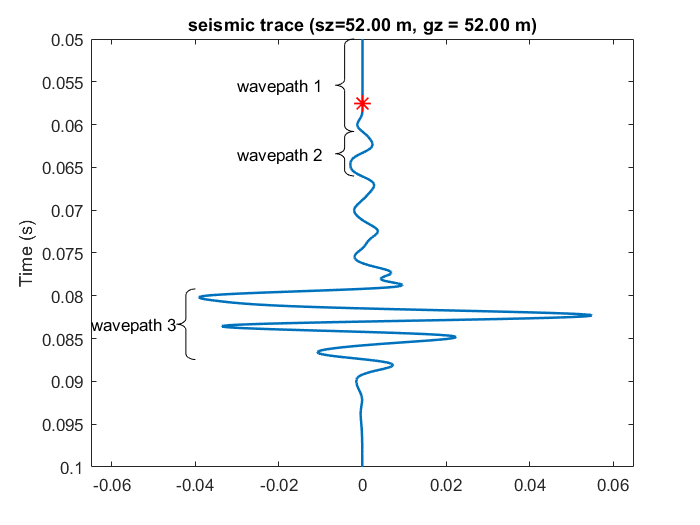

hdTr = csg0.plotTrace(idxTrace, 'FA', 'y', 'xlim', [0.05, 0.1], ...
    'ylim', [-0.065 0.065], 'LineWidth', 1.5, 'tVertical', 'y');
drawbrace([0.0608, -0.002], [0.05, -0.002],  6, 'Color', 'k');
drawbrace([0.066, -0.002], [0.0608, -0.002],  6, 'Color', 'k');
drawbrace([0.08744, -0.04], [0.0792, -0.04],  6, 'Color', 'k');
text(0.0554, -0.03, 'wavepath 1');
text(0.0634, -0.03, 'wavepath 2');
text(0.0833, -0.065, 'wavepath 3'); 
csg0.saveseis(hdTr, 'trace', 'idxTrace', idxTrace);

% refraction/first arrival wavepath
% first arrival is not a perfect ricker; only the first trough is window;
tMute=0.0608;
wp0 = csg0.getWP(idxTrace, 'tEnd', tMute, 'wavetype', 'direct');

Computing wave path (sz=52.00 m, gz = 52.00 m) ... 
Elapsed time is 23.587978 seconds.


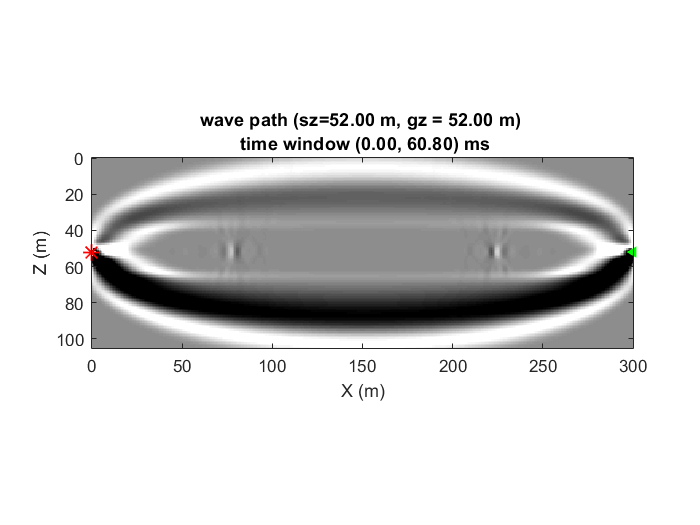

Ghostscript error. Rolling back to GS 9.10 or Matlab R2014a may possibly solve this:
 * <a href="https://github.com/altmany/export_fig/issues/12#issuecomment-61467998">https://github.com/altmany/export_fig/issues/12#issuecomment-61467998</a> (GS 9.10)
 * <a href="https://github.com/altmany/export_fig/issues/20#issuecomment-63826270">https://github.com/altmany/export_fig/issues/20#issuecomment-63826270</a> (R2014a)

export_fig error. Please ensure:
  that you are using the <a href="https://github.com/altmany/export_fig/archive/master.zip">latest version</a> of export_fig
  and that you have <a href="http://www.ghostscript.com">Ghostscript</a> installed
  and that you do not have multiple versions of export_fig installed by mistake
  and that you did not made a mistake in the expected input arguments

If the problem persists, then please <a href="https://github.com/altmany/export_fig/issues">report a new issu

Error using ghostscript>gs_path (line 154)
Ghostscript not found. Have you installed it from www.ghostscript.com?

Error in ghostscript (line 48)
        [varargout{1:nargout}] = system([gs_command(gs_path()) cmd]);

Error in eps2pdf

%wp0.plotHist(wp0);
hd_wp0=wp0.plotWP();
wp0.savefig(hd_wp0);

% refle wavepath; a cycle right after the first trough
t1=0.0608; t2=0.066;
wp1 = csg0.getWP(idxTrace, 'tStart', t1, 'tEnd', t2, 'wavetype', 'refl', 'reflCoeff', refl_ss);
hd_wp1=wp1.plotWP();
wp1.savefig(hd_wp1);

% refle wavepath
t1=0.0792; t2=0.08744;
wp2 = csg0.getWP(idxTrace, 'tStart', t1, 'tEnd', t2, 'wavetype', 'refl', 'reflCoeff', refl_ss);
hd_wp2=wp2.plotWP();
wp2.savefig(hd_wp2);